#### **VISUALISING**

**Frequency of Covid-19 Tests**

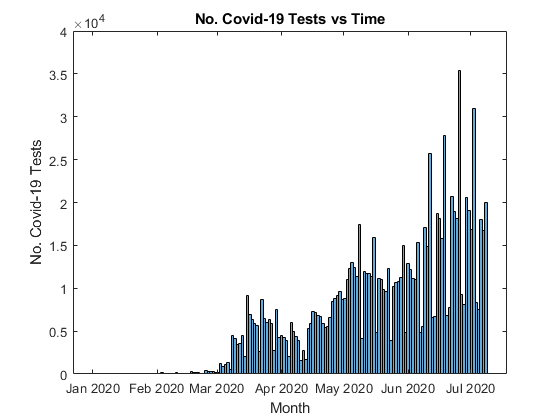

histogram(testingData.datetime)
title("No. Covid-19 Tests vs Time")
xlabel("Month")
ylabel("No. Covid-19 Tests")

**Frequency of Covid-19 Cases**

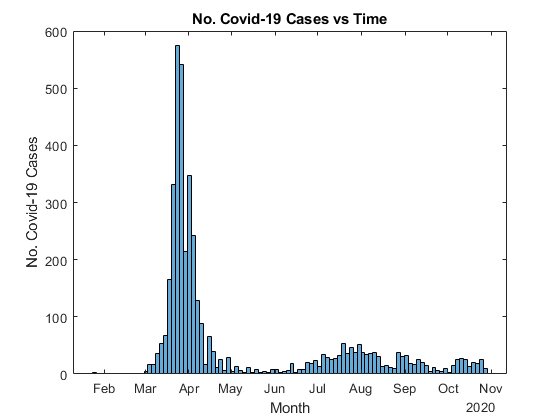

histogram(casesData.datetime, 100)
title("No. Covid-19 Cases vs Time")
xlabel("Month")
ylabel("No. Covid-19 Cases")

**Visualising the Categorical Data (testing dataset)**

% summary of the data
summary(testingData(:, ["lhd_2010_name"]))

Variables:

    lhd_2010_name: 1048575×1 categorical

        Values:

            Central Coast                 45067
            Far West                       2393
            Hunter New England       1.1838e+05
            Illawarra Shoalhaven          49895
            Mid North Coast               22125
            Murrumbidgee                  20681
            Nepean Blue Mountains         61781
            Network with Vic               3708
            Northern NSW                  28911
            Northern Sydney          1.3523e+05
            South Eastern Sydney     1.3632e+05
            South Western Sydney     1.0836e+05
            Southern NSW                  18058
            Sydney                   1.0305e+05
            Western NSW                   25508
            Western Sydney           1.1739e+05
            NumMissing                    51713



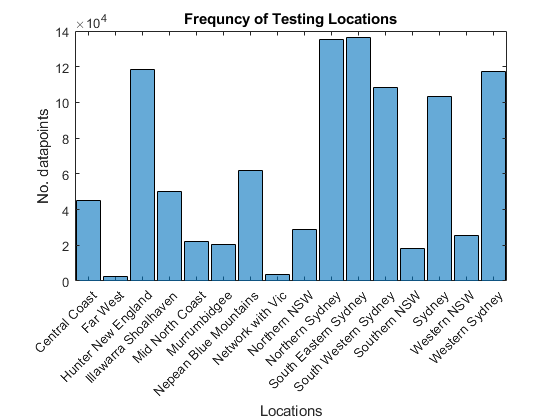

% histrogram
histogram(testingData.lhd_2010_name);
title("Frequncy of Testing Locations");
xlabel("Locations")
ylabel("No. datapoints")

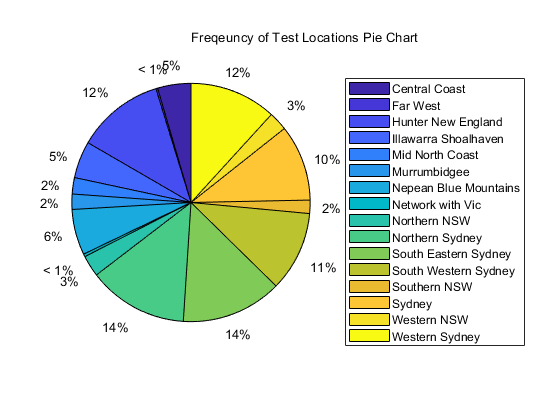

% pie chart
tbl = tabulate(testingData.lhd_2010_name);
pie(cell2mat(tbl(:, 2)));
legend(tbl(:, 1), 'Location', 'southeastoutside');
text(0, 1.4, "Freqeuncy of Test Locations Pie Chart")

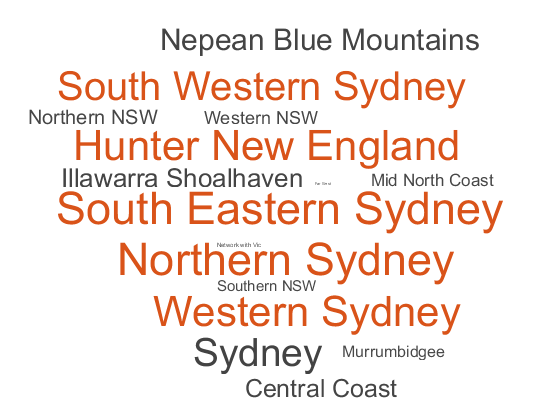

% word cloud
wordcloud(testingData.lhd_2010_name)

**Visualising the Categorical Data (businesses dataset)**

% summary
summary(businessesData(:, ["business_reported_industry"]))

Variables:

    business_reported_industry: 94121×1 categorical

        Values:

            Agriculture                                                1336  
            Arts and entertainment                                     1673  
            Auctions and open houses                                   1477  
            Beauty, nail, waxing, tanning and hairdressing salons      4864  
            Betting agencies                                            136  
            Caravan and Camping                                         431  
            Community centres and Hall                                 1286  
            Community sport for adults                                  437  
            Community sport for kids                                    604  
            Construction                                               2068  
            Drive-In                                                     33  
            Education & training           

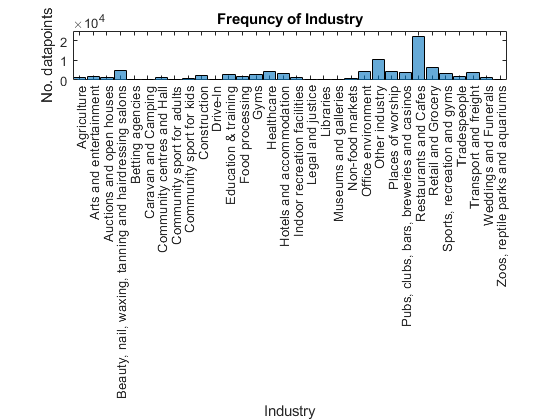

% histogram
histogram(businessesData.business_reported_industry);
title("Frequncy of Industry");
xlabel("Industry")
ylabel("No. datapoints")

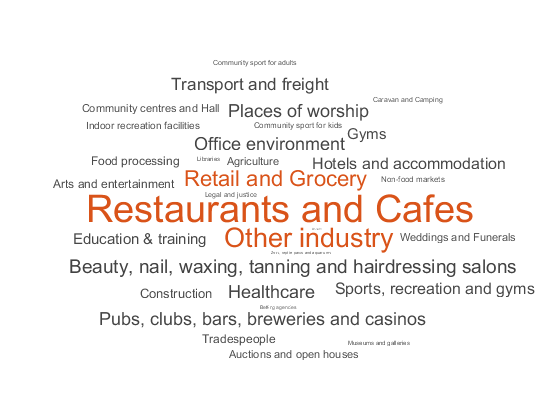

% word cloud
wordcloud(businessesData.business_reported_industry)

**Visualising the Categorical Data (cases dataset)**

% summary
summary(casesData(:, ["lhd_2010_name"]))

Variables:

    lhd_2010_name: 4222×1 categorical

        Values:

            Central Coast              129   
            Far West                     2   
            Hunter New England         299   
            Illawarra Shoalhaven       138   
            Mid North Coast             53   
            Murrumbidgee                46   
            Nepean Blue Mountains      206   
            Network with Vic            11   
            Northern NSW                59   
            Northern Sydney            603   
            South Eastern Sydney       794   
            South Western Sydney       552   
            Southern NSW                64   
            Sydney                     348   
            Western NSW                 49   
            Western Sydney             541   
            NumMissing                 328   



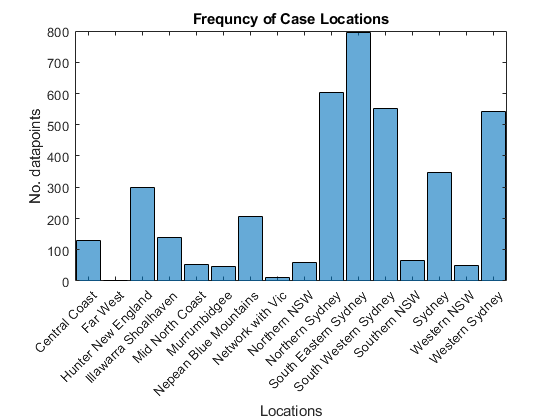

% histogram
histogram(casesData.lhd_2010_name);
title("Frequncy of Case Locations");
xlabel("Locations")
ylabel("No. datapoints")

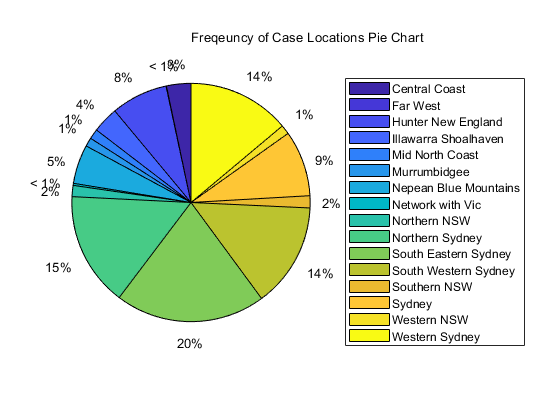

% pie chart
tbl = tabulate(casesData.lhd_2010_name);
pie(cell2mat(tbl(:, 2)));
legend(tbl(:, 1), 'Location', 'southeastoutside');
text(0, 1.4, "Freqeuncy of Case Locations Pie Chart")

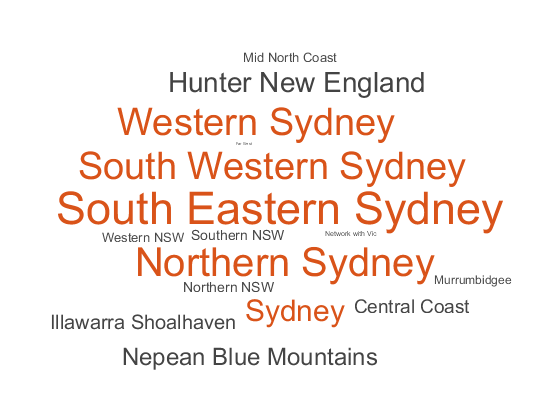

% word cloud
wordcloud(casesData.lhd_2010_name)

**Geographical Coordinates (cases dataset)**

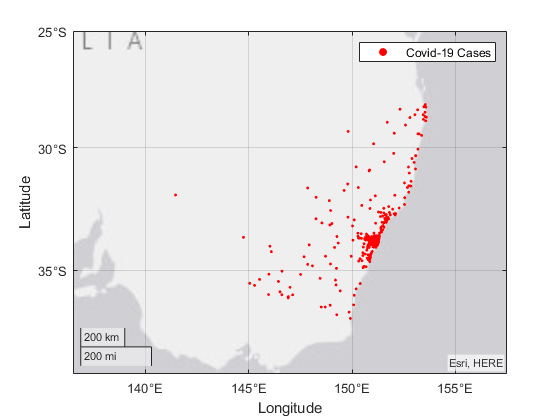

geoscatter(casesData.latitude, casesData.longitude, 5, "red", "filled", "o")
geolimits([-39 -25],[139 155])
legend("Covid-19 Cases")

**Geographical Coordinates (tests dataset)**

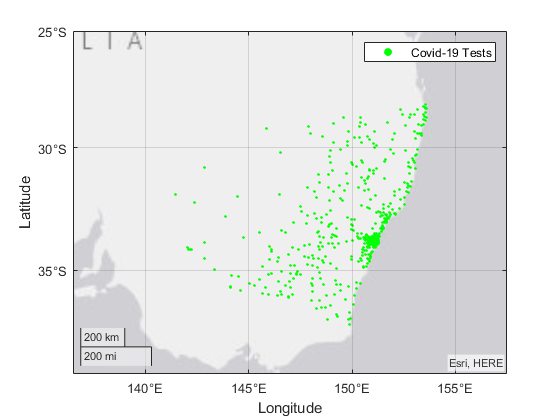

geoscatter(testingData.latitude, testingData.longitude, 5, "green", "filled", "o")
geolimits([-39 -25],[139 155])
legend("Covid-19 Tests")

**Geographical Representation of COVID-safe Businesses**

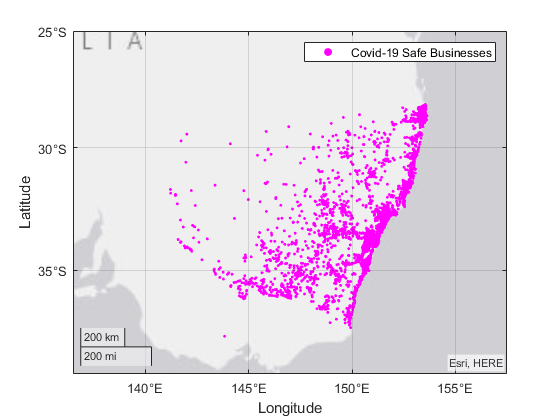

geoscatter(businessesData.latitude(businessesData.business_reported_state == "NSW"), businessesData.longitude(businessesData.business_reported_state == "NSW"), 5, "magenta", "filled", "o")
geolimits([-39 -25],[139 155])
legend("Covid-19 Safe Businesses")